sys = Rad229_MRI_sys_config;

## A. Conventional Flow Compensated Slice-Select Gradient

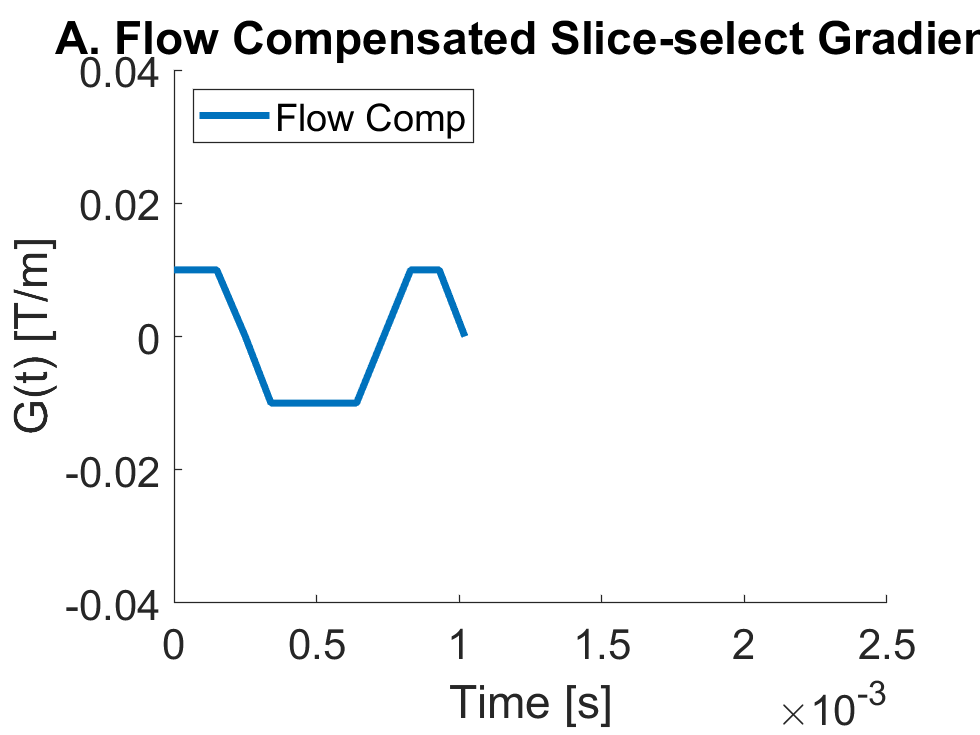

clear params;
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);


t_FC = (0:params.dt:(length(G_FC)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FC,G_FC); axis([0 2.5e-3 -40e-3 40e-3]);
  title('A. Flow Compensated Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('Flow Comp','Location','NorthWest')

## B. Conventional Flow Encoded Gradient

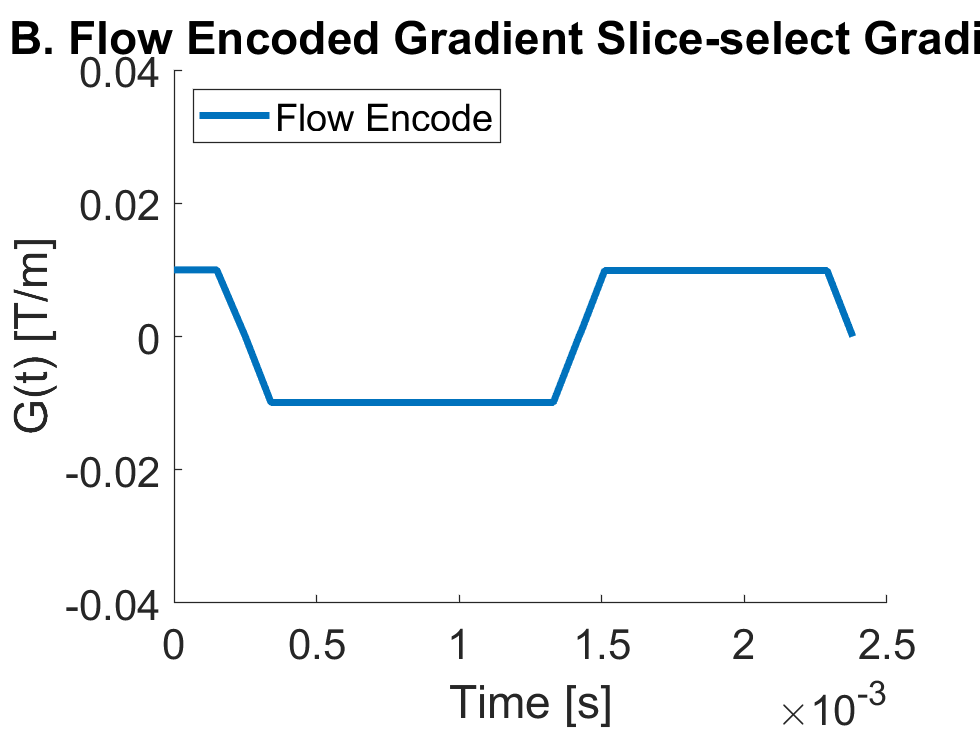

clear params;
params.mode = 'free';
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

params.VENC = 1.5;      % Velocity ENCoding strength m/s
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

[G_FE, ~] = conventional_flowencode(params);
t_FE= (0:params.dt:(length(G_FE)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FE,G_FE); axis([0 2.5e-3 -40e-3 40e-3]);
  title('B. Flow Encoded Gradient Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('Flow Encode','Location','NorthWest')

## C. Conventional Flow Compensated/Encoded Gradients

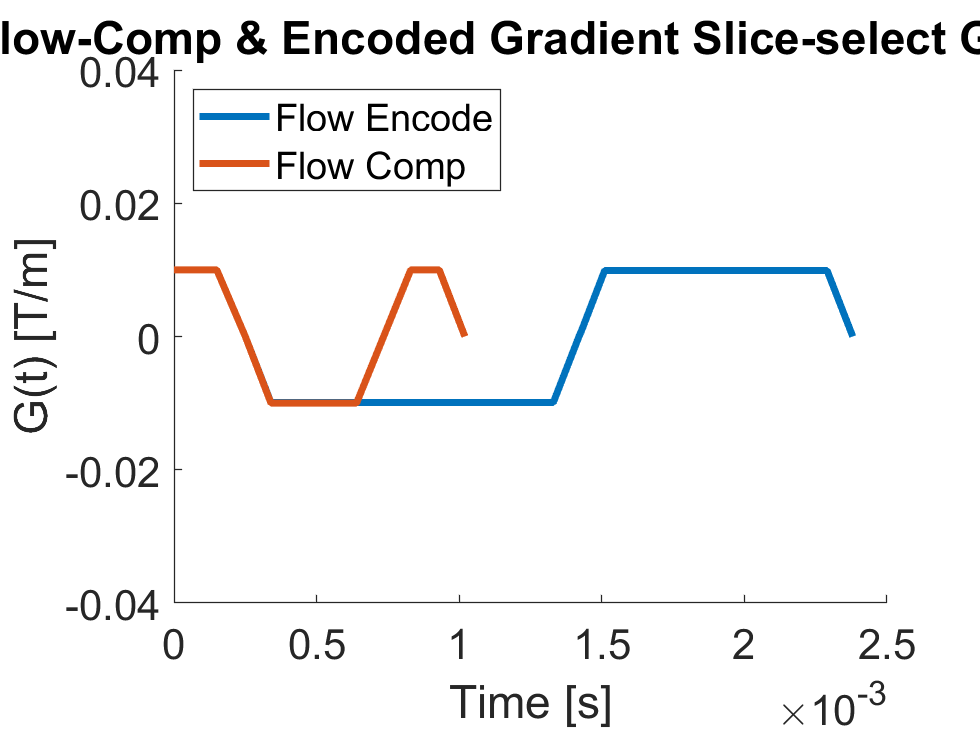

clear params;
params.mode = 'free';
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);

params.VENC = 1.5;      % Velocity ENCoding strength m/s
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

[G_FE, ~] = conventional_flowencode(params);

t_FC = (0:params.dt:(length(G_FC)-1)*params.dt);
t_FE = (0:params.dt:(length(G_FE)-1)*params.dt);

set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',18);
figure; hold on;
  plot(t_FE,G_FE); plot(t_FC,G_FC);   axis([0 2.5e-3 -40e-3 40e-3]);
  title('C. Flow-Comp & Encoded Gradient Slice-select Gradient');
  xlabel('Time [s]'); ylabel('G(t) [T/m]'); legend('Flow Encode','Flow Comp','Location','NorthWest')

## D. Optimized Symmetric Bipolar Flow Encoding Gradients

clear params;
params.mode = 'free';
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.VENC = 1.5;   % Velocity ENCoding strength m/s

GAM = 2*pi*42.57e6;       % rad/(s*T)
DeltaM1 = pi/(GAM*params.VENC);  % T/m x s^2

% M0 and M1 units here converted to [mT/m*ms^N] for GrOpt
params.moment_params = [];
params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -1e6*M0S(1,end), 1.0e-3];             % Target M0
params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)+DeltaM1/2), 1.0e-3];   % Target M1

[G_FE, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 1.875 1.563 1.719 1.641 1.680 1.660 1.670 1.675 1.677 Final TE = 1.677 ms


FE_pos = horzcat(G_ss,G_FE);

params.moment_params = [];
params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, -1e6*M0S(1,end), 1.0e-3];             % Target M0
params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)-DeltaM1/2), 1.0e-3];   % Target M1

[G_FE, ~] = get_min_TE_free(params, 5.0);

Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.133 1.152 1.143 1.138 1.135 Final TE = 1.135 ms


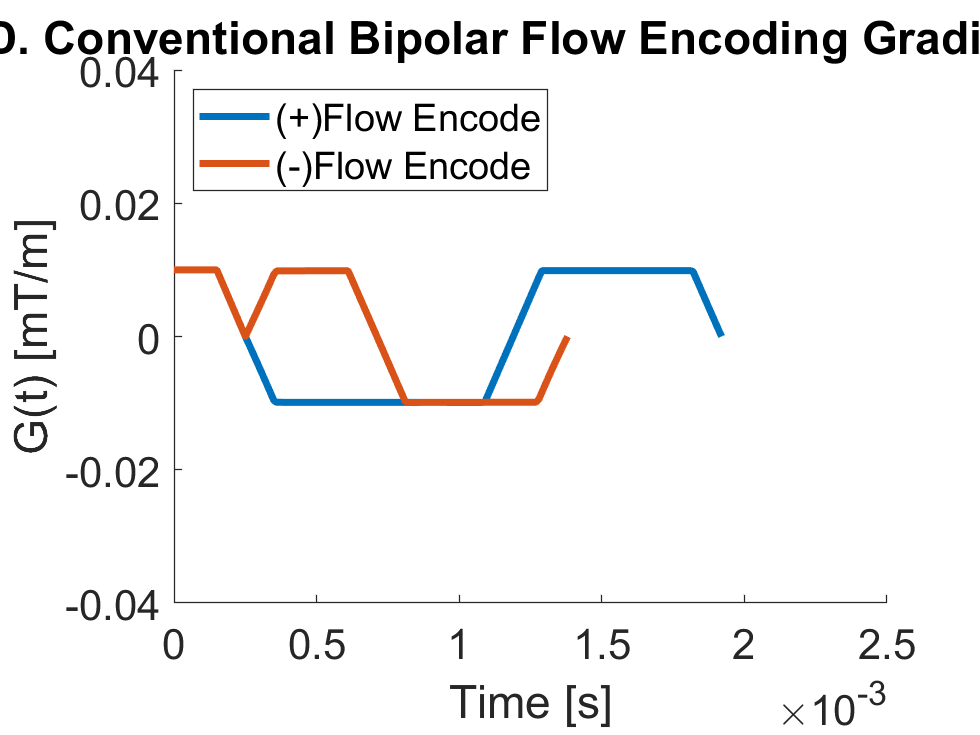

FE_neg = horzcat(G_ss,G_FE);

tFE_pos = (0:params.dt:(length(FE_pos)-1)*params.dt);
tFE_neg = (0:params.dt:(length(FE_neg)-1)*params.dt);
figure; hold on;
  plot(tFE_pos,FE_pos); plot(tFE_neg,FE_neg);  axis([0 2.5e-3 -40e-3 40e-3]);
  title('D. Conventional Bipolar Flow Encoding Gradients');
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('(+)Flow Encode','(-)Flow Encode','Location','NorthWest')

## E. Optimized Asymmetric Flow Encoding Gradients

% This code has a linear (not a bisection) search for the optimal alpha, which is slow ;(
clear params;
params.mode = 'free';
params.gmax = sys.G_max; % Maximum gradient amplitude, T/m
params.smax = sys.S_max; % Maximum slew rate, T/m/s
params.dt = sys.dt;      % Gradient raster time, s
params.g_ss = 10e-3;     % Slice select gradient amplitude, T/m
params.p_ss = 0.15e-3;   % Slice select gradient plateau, [s]

[G_FC, M0S, M1S, t_ss, G_ss] = conventional_flowcomp(params);

params.VENC = 1.5;      % Velocity ENCoding strength m/s
params.M0S = M0S;       % Slice select M0 (from above)    
params.M1S = M1S;       % Slice select M1 (from above)
params.G_ss = G_ss;     % Slice select gradient (from above)

t_vec = 0:params.dt:(length(G_ss)-1)*params.dt;

GAM = 2*pi*42.57e6;       % rad/(s*T)
DeltaM1 = pi/(GAM*params.VENC);  % T/m x s^2
    
for i = 0:0.025:0.5   % Loop over possible values of alpha

    alpha = i;
    params.moment_params = [];
    params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, 1e6*-M0S(1,end), 1.0e-3];                   % Target M0
    params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)+(DeltaM1*alpha)), 1.0e-3];   % Target M1
    [G1, T1] = get_min_TE_free(params, 5.0);
    FE_pos = horzcat(G_ss,G1);
    
    params.moment_params = [];
    params.moment_params(:,end+1) = [0, 0, t_ss, -1, -1, 1e6*-M0S(1,end), 1.0e-3];                       % Target M0
    params.moment_params(:,end+1) = [0, 1, t_ss, -1, -1, 1e9*(-M1S(1,end)-(DeltaM1*(1-alpha))), 1.0e-3];   % Target M1
    params.TE = T1;
    [G2, debug] = gropt(params);
    T2 = length(G2)*params.dt*1000;
    FE_neg = horzcat(G_ss,G2);
    
    if abs(T1-T2) <= 0.01 && debug == 0   % Stop when the waveforms are equal and constraints met 
        break
    end
    
end

Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.820 0.840 0.830 0.825 0.823 Final TE = 0.825 ms
Testing TE = 2.500 1.250 0.625 0.938 0.781 0.859 0.898 0.879 0.889 0.894 0.896 Final TE = 0.896 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 0.977 0.957 0.967 0.962 0.964 Final TE = 0.967 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.035 1.025 1.021 1.023 Final TE = 1.025 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.016 1.055 1.074 1.084 1.079 1.077 Final TE = 1.077 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.133 1.113 1.123 1.128 1.125 Final TE = 1.125 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.211 1.191 1.182 1.177 1.174 Final TE = 1.177 ms
Testing TE = 2.500 1.250 0.625 0.938 1.094 1.172 1.211 1.230 1.221 1.216 1.213 Final TE = 1.216 ms
Testing TE = 2.500 1.250 1.875 1.563 1.406 1.328 1.289 1.270 1.260 1.265 1.267 Final TE = 1.267 ms
Testing TE = 2.500 1.250 1.875 1.563 1.406 1.328 1.289 1.309 1.299 1.304 1.306 Final TE = 1.306 ms
Testing TE

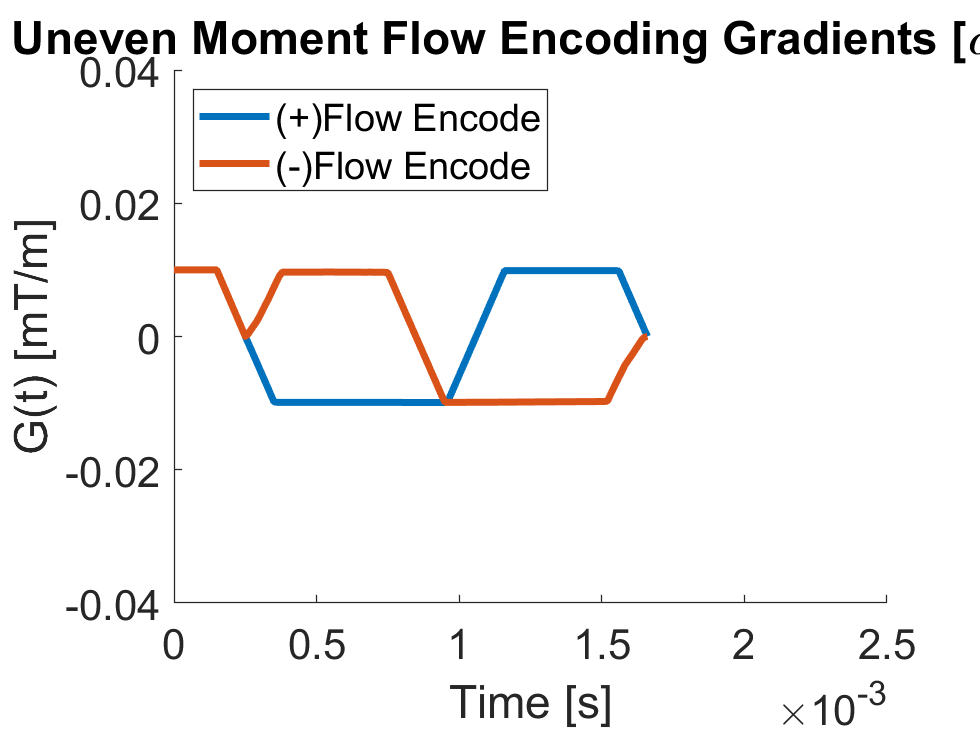

tFE_pos = (0:params.dt:(length(FE_pos)-1)*params.dt);
tFE_neg = (0:params.dt:(length(FE_neg)-1)*params.dt);
figure; hold on;
  title(['E. Uneven Moment Flow Encoding Gradients [\alpha=',num2str(alpha),']']);
  plot(tFE_pos,FE_pos); plot(tFE_neg,FE_neg);  axis([0 2.5e-3 -40e-3 40e-3]);
  xlabel('Time [s]'); ylabel('G(t) [mT/m]'); legend('(+)Flow Encode','(-)Flow Encode','Location','NorthWest') 